addpath brainwaves
addpath lidar
addpath color_masking
addpath utils

moj = get_mojave();

moj.setup();

Setup complete


moj.lidar.lidar_setup();

lidar_fig = figure("Name", "Lidar", "NumberTitle", "off", "Visible","on");
ang_fig = figure("Name", "Angular Brainwaves", "NumberTitle", "off", "Visible","on");
vel_fig = figure("Name", "Velocity Brainwaves", "NumberTitle","off", "Visible","on");

steer_angle = 0;
moj.steer(steer_angle);

ans = 75

Elapsed time is 4.356668 seconds.


ans = 196

Elapsed time is 5.980830 seconds.


ans = 3536

Elapsed time is 7.453122 seconds.


ans = 0

Elapsed time is 8.485193 seconds.


ans = 0

Elapsed time is 9.587345 seconds.


ans = 1

Elapsed time is 10.578044 seconds.


ans = 490

Elapsed time is 11.550112 seconds.


ans = 172

Elapsed time is 12.427465 seconds.


ans = 71

Elapsed time is 13.348670 seconds.


ans = 115

Elapsed time is 14.260588 seconds.


ans = 131

Elapsed time is 15.134977 seconds.


ans = 198

Elapsed time is 16.078017 seconds.


ans = 1076

Elapsed time is 17.049369 seconds.


ans = 10698

Elapsed time is 17.953981 seconds.


ans = 19159

Elapsed time is 18.879345 seconds.


ans = 16633

Elapsed time is 19.850087 seconds.


ans = 22263

Elapsed time is 20.882264 seconds.


ans = 1515

Elapsed time is 21.805883 seconds.


ans = 0

Elapsed time is 22.773968 seconds.


ans = 92

Elapsed time is 23.681483 seconds.


ans = 544

Elapsed time is 24.746695 seconds.


ans = 648

Elapsed time is 25.668542 seconds.


ans = 68

Elapsed time is 26.579505 seconds.


ans = 111

Elapsed time is 27.602391 seconds.


ans = 54

Elapsed time is 28.668245 seconds.


ans = 48

Elapsed time is 29.610452 seconds.


ans = 571

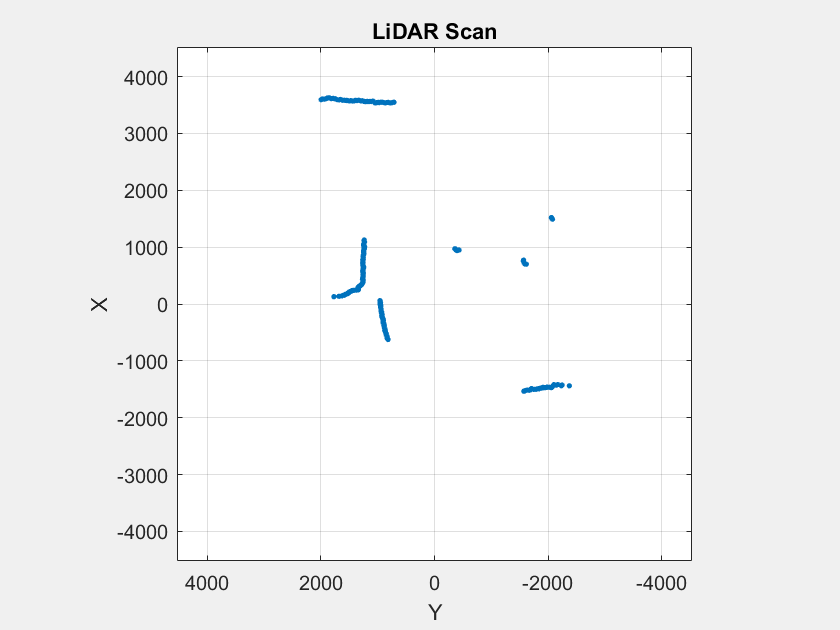

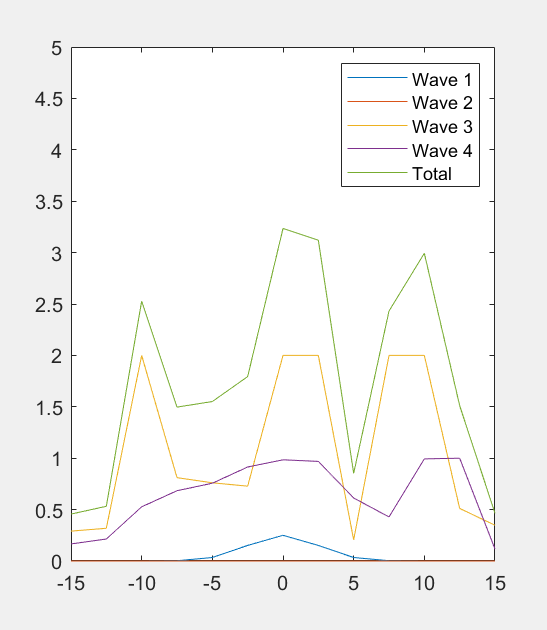

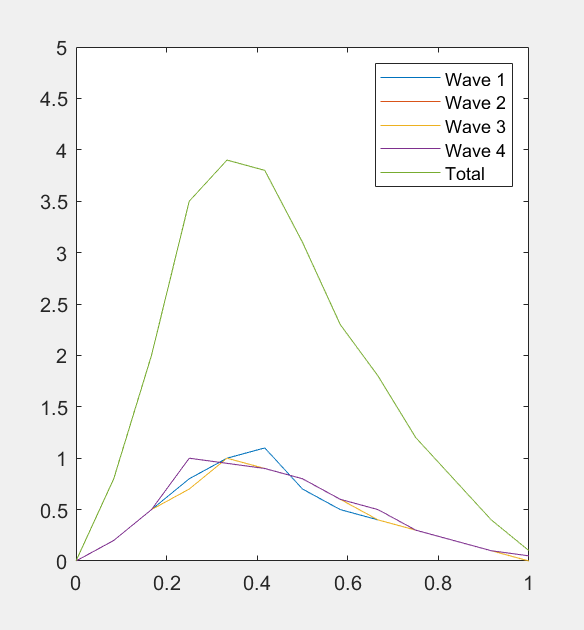

Elapsed time is 30.777098 seconds.


% leave_depot(moj);
wave1 = @(m) go_straight(m);
wave2 = @(m) avoid_color(m,@(i) grass_mask(i));
wave3 = @(m) lidar_wave(m);
wave4 = @(m) lidar_inside_brainwave(m);
wave5 = @(m) follow_color(m,@(i) beige_mask(i));
arb_to_slolem = arbiter({wave1 wave2 wave3 wave5}, linspace(0, 1, 13), linspace(-15,15, 13), moj);
run_robot(moj, arb_to_slolem, 5);

moj.lidar.tilt_lidar(10);

wave1 = @(m) go_straight(m);
wave2 = @(m) maintain_dist_from_cone(m,@(i) cone_mask(i));
wave3 = @(m) lidar_bridge(m);
wave4 = @(m) lidar_wave(m);
arb_slolem = arbiter({wave4}, linspace(0, .9, 13), linspace(-15,15, 13), moj);
run_robot(moj,arb_slolem,2)

vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2778    0.5660    0.7227    0.4424    0.8537    1.0946    0.7608    0.8928    0.3593    0.4744    0.8734    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 4.885813 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.1282    0.5110    0.7317    0.4226    1.0560    1.0917    1.0220    0.6526    0.4306    0.6786    0.7389    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 6.672733 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3827    0.4554    0.8928    0.8810    0.8975    1.0682    0.7860    1.0120    0.0186    0.4970    0.8284    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 7.769869 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3828    0.6811    0.7592    0.9347    1.0808    1.0932    1.0373    0.9653    0.3368    0.4454    0.8598    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 8.421264 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3346    0.5817    0.8340    0.8509    0.9134    1.0965    0.9978    0.9342    0.0207    0.6481    0.9023    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 9.129500 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2411    0.7507    0.7436    0.7319    1.0325    1.0895    0.4848    0.9353    0.1888    0.5159    0.7729    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 9.822017 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3204    0.8740    0.8622    0.6942    1.0494    1.0931    0.8287    0.7476    0.3645    0.7915    0.8194    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 12.104372 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3065    0.9922    1.0110    0.8524    0.9147    1.0976    0.8810    0.9958    0.5464    0.7269    0.9016    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 13.244970 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3306    0.8710    0.9788    0.8556    1.0293    1.0943    1.0136    0.9764    0.1022    0.4542    0.8778    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 14.655898 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3718    0.9641    0.6209    0.7959    1.0983    1.0929    0.9711    0.6187    0.3001    0.4909    0.8949    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 15.603334 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2864    0.9542    1.0100    0.6498    0.8678    1.0204    0.6034    0.9966    0.1660    0.3874    0.9221    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 16.352191 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3367    0.9679    1.0296    0.5092    1.0992    1.0183    0.9308    0.6878    0.4693    0.7080    0.8888    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 16.942589 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3828    0.9529    0.6506    1.0075    0.9803    1.0938    0.8230    0.7384    0.5372    0.4408    0.8677    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 17.772607 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2373    1.0186    1.0703    0.8420    1.0550    1.0929    1.0389    0.9096    0.9256    0.7584    0.8956    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 18.350185 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2533    0.9810    0.9266    0.9748    0.8631    1.0912    1.0560    0.9586    0.3751    0.8051    0.6960    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 18.898829 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3614    0.7397    0.7382    0.5721    1.0971    1.0457    1.0823    0.9978    0.0160    0.6167    0.8934    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 19.482907 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.4660    0.6927    0.6900    0.8511    0.9533    1.0921    0.9699    0.7943    2.0000    0.4900    0.6986    2.0000    2.0000


vel_result = 0.3000

ang_result = 5

Elapsed time is 20.001585 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.4648    0.7087    0.9501    1.0250    1.0503    1.0914    0.8674    0.9554    0.1668    0.5083    0.8863    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 20.688987 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.4294    0.3910    0.9401    0.9324    0.7003    1.0905    0.9755    0.9470    0.3227    0.5081    0.8341    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 21.659575 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2637    1.0075    0.8381    0.9046    1.0223    1.0664    0.7520    0.9723    0.3067    0.7487    0.8476    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 22.451740 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3805    0.8245    0.9720    0.7086    0.7666    1.0931    0.7786    0.8242    0.1891    0.6219    0.8886    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 23.281163 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.4427    0.9108    0.7522    2.0000    1.0090    1.0913    1.0205    1.0238    0.0278    0.5352    0.9023    2.0000    2.0000


vel_result = 0.3000

ang_result = -7.5000

Elapsed time is 24.036960 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.1553    0.9453    1.0041    1.0213    0.7300    1.0947    2.0000    0.9853    0.0183    0.8484    0.8604    2.0000    2.0000


vel_result = 0.3000

ang_result = 0

Elapsed time is 24.903899 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.2356    0.7840    0.9976    2.0000    1.0099    1.0959    1.0065    0.9472    0.2372    0.4825    0.8454    2.0000    2.0000


vel_result = 0.3000

ang_result = -7.5000

Elapsed time is 25.555734 seconds.


vel_wave =          0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave =     0.3963    0.6227    0.6933    0.7067    0.7246    1.0974    1.0159    0.8646    0.8697    0.3393    0.8810    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 26.119784 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4403    0.6244    0.6970    0.8578    0.7985    1.0898    0.8168    1.0366    0.5091    0.5711    0.7995    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 26.864638 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3640    0.9644    0.6757    0.5054    0.6528    1.0924    0.9701    0.8851    0.3185    0.5226    0.8985    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 27.690373 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2493    0.7134    0.8509    0.9783    1.0361    1.0904    0.9383    0.9825    0.3981    0.4684    0.8840    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 28.321726 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1783    0.7670    0.7784    0.7533    1.0941    1.0928    0.9441    0.9601    0.2828    0.5204    0.8231    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 29.024920 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1684    0.6150    1.0895    1.0008    1.0105    1.0869    0.8256    0.9753    0.2254    0.6526    0.7725    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 29.728213 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3797    0.8900    0.5964    0.6020    1.0393    1.0918    0.9663    1.0036    0.5848    0.3781    0.9009    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 30.463861 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4477    0.6828    0.9838    2.0000    0.8658    1.0938    2.0000    0.5149    0.0306    0.5390    0.7340    2.0000    2.0000


vel_result = 0.3000

ang_result = -7.5000

Elapsed time is 31.175092 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4595    0.6225    0.8858    0.8215    1.0549    1.0947    0.7258    0.9340    0.6866    0.4517    0.8715    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 32.033339 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1678    0.7341    0.6635    0.8667    0.9558    1.0659    0.7817    0.9109    0.0254    0.5980    0.8953    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 32.836419 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3351    0.7597    0.6026    0.9803    1.0044    1.0909    0.8306    0.8726    0.6353    0.6177    0.8009    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 33.491143 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4194    0.9268    0.7655    0.6546    1.0043    1.0933    1.0304    0.8150    0.5455    0.5801    0.7541    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 34.051388 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1973    0.8868    0.6810    0.8355    1.0954    1.0455    0.6644    0.8757    0.2106    0.4361    0.7541    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 34.696281 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2680    0.6273    0.7390    1.0776    1.0096    1.0943    0.6428    0.9893    0.5253    0.7228    0.8655    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 35.273400 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1280    0.8509    0.4493    0.7291    0.9741    1.0965    2.0000    0.9839    0.0201    0.7797    0.8126    2.0000    2.0000


vel_result = 0.3000

ang_result = 0

Elapsed time is 35.830526 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3745    0.7688    0.8687    0.6134    1.0285    1.0937    0.8747    1.0244    0.5400    0.6225    0.9076    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 36.466967 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2401    1.0540    1.0230    0.8527    0.9188    1.0937    0.7555    1.0144    0.0221    0.5630    0.7825    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 37.124530 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4428    0.8785    0.7755    0.9724    0.7544    1.0944    0.9502    0.8672    0.3896    0.7852    0.8761    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 37.778285 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4815    2.0000    0.6008    0.7677    0.9230    1.0937    1.0230    1.0399    0.4621    0.4738    0.8181    2.0000    2.0000


vel_result = 0.3000

ang_result = -12.5000

Elapsed time is 38.346345 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2581    0.9071    0.7541    0.6259    0.9102    1.0959    0.6112    0.7224    0.4199    0.5310    0.8173    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 38.982515 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2561    0.5366    0.9778    0.8919    0.9352    1.0923    0.7773    0.9978    0.1558    0.6844    0.7531    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 39.575343 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2798    0.6467    0.7657    0.9520    0.9538    1.0698    0.7168    0.9812    0.5537    0.6238    0.9263    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 40.179870 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2840    0.8062    0.7868    0.7672    1.0627    1.0969    0.4561    0.8834    0.6493    0.6674    0.6549    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 40.755860 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4392    0.5977    0.8688    0.8477    0.8225    1.0874    1.0055    1.0126    0.6429    0.5722    0.8966    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 41.515770 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3140    0.6165    0.9794    0.6154    1.0765    1.0914    0.9070    1.0251    0.3433    0.6950    0.9198    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 42.244243 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3161    0.6814    0.7646    0.8312    0.9747    1.0939    1.0640    0.9541    0.0230    0.4432    0.9112    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 43.056166 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1739    0.6224    0.8173    0.8159    1.0464    1.0972    2.0000    0.8880    0.0168    0.5350    0.8787    2.0000    2.0000


vel_result = 0.3000

ang_result = 0

Elapsed time is 43.956230 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4307    0.4041    0.9535    0.8632    0.9771    1.0967    0.9038    0.8028    0.6169    0.6547    0.7675    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 44.868858 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3783    1.0277    0.8213    0.8902    1.0534    1.0908    2.0000    1.0160    0.1885    0.5450    0.8530    2.0000    2.0000


vel_result = 0.3000

ang_result = 0

Elapsed time is 45.476927 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2348    0.9789    0.9736    0.7454    0.7970    1.0659    0.9370    0.9573    0.3607    0.5799    0.9100    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 46.085051 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3380    0.4125    0.6795    0.6788    1.0752    1.0922    0.5414    0.9441    0.3777    0.7169    0.8502    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 46.756939 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3294    0.6275    0.5960    0.9974    0.9954    1.0587    0.9799    0.7954    0.4124    0.5057    0.8348    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 47.460903 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2763    0.9700    0.6531    0.6057    0.7346    1.0942    0.9113    0.8962    0.3447    0.4648    0.9201    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 48.037503 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4103    1.0082    0.7363    0.6367    1.0548    1.0942    0.8039    0.9636    1.1194    0.6110    0.9038    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 48.646720 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1272    2.0000    0.9798    0.7843    0.8952    1.0158    0.9866    1.0187    0.6409    0.7237    0.8308    2.0000    2.0000


vel_result = 0.3000

ang_result = -12.5000

Elapsed time is 49.258784 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3655    0.6529    0.7859    0.4535    0.9470    1.0929    1.0275    0.9759    0.5276    0.7925    0.7752    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 49.895640 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1463    1.0205    0.6373    0.8762    1.0356    1.0763    0.9874    0.9461    0.1973    0.8140    0.8602    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 50.424712 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2753    0.8021    2.0000    0.7510    1.0929    1.0946    0.5412    0.8798    0.5882    0.6122    0.7797    2.0000    2.0000


vel_result = 0.3000

ang_result = -10

Elapsed time is 51.097988 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.5022    0.7977    1.0389    2.0000    1.0642    1.0942    0.8554    0.8446    0.3545    0.5774    0.9015    2.0000    2.0000


vel_result = 0.3000

ang_result = -7.5000

Elapsed time is 51.690362 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.4559    0.8801    0.7074    0.8297    0.9518    1.0932    0.9298    0.8497    0.0245    0.5559    0.8707    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 52.252137 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.5213    0.9095    1.0430    0.5363    0.8742    1.0935    0.8777    0.9393    0.7441    0.7204    0.8937    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 52.849790 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2406    0.5405    0.9509    0.8106    0.8842    1.0926    0.9217    0.9826    0.5148    0.8371    0.8171    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 53.445362 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2531    0.7493    0.9902    0.7203    0.8789    1.0880    1.0154    0.9476    0.4275    0.5389    0.8176    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 54.119206 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1416    0.9986    1.0330    0.5541    0.8433    1.0574    1.0313    0.9080    0.0175    0.7038    0.8982    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 54.819512 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.3071    0.9613    1.0197    0.7246    0.9062    1.0934    0.8595    1.0045    0.0269    0.6478    0.8508    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 55.639611 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.1535    0.8424    0.8434    0.9851    1.0441    1.0870    0.7601    0.8326    0.3722    0.4252    0.8250    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 56.862965 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2035    0.8469    0.5798    0.8854    0.9247    1.0919    1.0639    0.9177    0.8222    0.4756    0.7478    2.0000    2.0000


vel_result = 0.3000

ang_result = 12.5000

Elapsed time is 57.976366 seconds.


vel_wave = 1×13
         0    0.2000    0.5000    0.7000    1.0000    0.9000    0.8000    0.6000    0.4000    0.3000    0.2000    0.1000         0


ang_wave = 1×13
    0.2396    1.0383    0.8948    0.5414    1.0583    1.0207    0.5727    0.9990    2.0000    0.3486    0.8382    2.0000    2.0000


vel_result = 0.3000

ang_result = 5

Elapsed time is 58.995802 seconds.


moj.lidar.lidar_shutdown();